## Results - Trajectory Planning

Here we will generate a minimum time trajectory for all joints based on user-input of ice-cream flavors. The manipulator begins at home configuration, then moves to the cone dispensing station. Then depending on user-input, the end-effector is moved to upto 3 locations, corresponding to each flavor, in the requested order (Flavor 1 at the bottom of the cone, Flavor 3 at the top). The manipulator will pause at each dispensing location for a set amount of time.  We also draw the last link configuration at each station to better visualize the overall trajectory. 

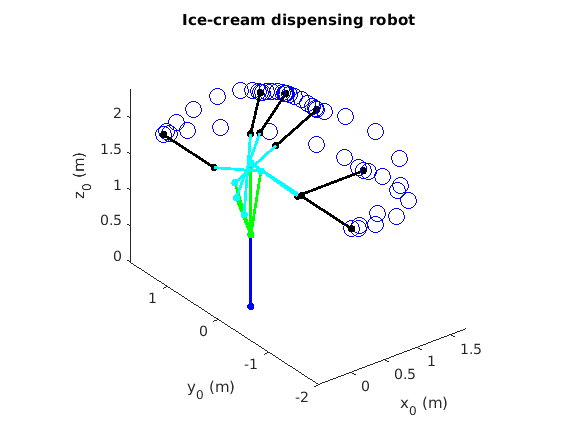

clear all 
close all

Flavor_1=3;
Flavor_2=2;
Flavor_3=1;

Q_mat = look_up_joint_angles(Flavor_1,Flavor_2,Flavor_3);
[m n]=size(Q_mat);

% Link parameters
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;

interval = 5; % Specify number of points in each trajectory

% Set positions
config_home = [0;0;0;0];
config_cone = [pi/2,0.2,0.2];
config_customer = [-pi/2,0,pi/4];

alpha=10; % Max angular acceleration of all joints (deg/s^2)

[t_mat, Traj_mat] = full_traj(config_home,config_cone,config_customer,gamma,alpha,interval,n,Q_mat);

for i=1:n+3
    current_traj=Traj_mat(:,:,i);
        for j=1:length(current_traj)
            % Specify DH table. 
            a_vec = [0, a2, a3, a4]; 
            alpha_vec = [pi/2, 0, 0, 0]; 
            d_vec = [d1, 0, 0, 0]; 
            
            % Specify theta from min time trajectory generated earlier.
            theta1=current_traj(1,j); theta2=current_traj(2,j); 
            theta3=current_traj(3,j); theta4=current_traj(4,j);
            theta_vec = [theta1, theta2 + pi/2, theta3 - pi/2 - gamma, theta4];
            
            % Compute FK and output H matrix and location of each frame in P_vec:
            [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
            
            plot_link_nc(P_vec,j,length(current_traj))
        end

        pause(1.5)
end
xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Trajectory planning of ice-cream dispensing robot')

## FUNCTIONS

function [tvec, traj] = trajplan(q0,qf,t0,alpha,interval)
% Computes minimal time trajectory 
    if qf>q0
        ts=sqrt((qf-q0)/alpha);
        t1=linspace(0,ts,interval);
        t2=linspace(ts,2*ts,interval);
        ang_pos1 = 0.5*alpha*t1.^2;
        ang_pos2 = -0.5*alpha*t2.^2 + 2*alpha*ts*t2 - alpha*ts^2;
        tvec=t0+[t1,t2];
        traj=(q0+[ang_pos1,ang_pos2]);
    end
    if q0>qf
        ts=sqrt((q0-qf)/alpha);
        t1=linspace(0,ts,interval);
        t2=linspace(ts,2*ts,interval);
        ang_pos1 = -0.5*alpha*t1.^2;
        ang_pos2 = -(-0.5*alpha*t2.^2 + 2*alpha*ts*t2 - alpha*ts^2);
        tvec=t0+[t1,t2];
        traj=(q0+[ang_pos1,ang_pos2]);
    end
    if q0==qf
        tvec=t0+linspace(0,0,2*interval);
        traj=q0*ones(1,2*interval);
    end
end

function [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec)
% This function calculates the homogeneous transformation matrix H using DH
% convention input parameters and outputs the final H^0_n, the position of all frames
% (P_vec), and all the H matrices.
H=eye(4);
P = [0;0;0;1];
P_vec = zeros(4,length(a_vec));
    for i=1:length(a_vec)
        a=a_vec(i); d=d_vec(i); alpha=alpha_vec(i); theta=theta_vec(i);
        H_tmp = [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta); ...
        sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta); ...
        0, sin(alpha), cos(alpha), d; ...
        0, 0, 0, 1];
       
        H=H*H_tmp;
        All_H(:,:,i) = H;
        P_vec(1:4,i) = H*P;
    end
end

function plot_link_nc(P_vec,current,end_condition)
% This function plots each link with input P_vec that describes the origin
% of each frame.
    A = [0 P_vec(1,:)];
    B = [0 P_vec(2,:)];
    C = [0 P_vec(3,:)];
    
    h1=plot3(A(1:2),B(1:2),C(1:2),'b.-','MarkerSize',12,'LineWidth',2);
    h2=plot3(A(2:3),B(2:3),C(2:3),'g.-','MarkerSize',12,'LineWidth',2);
    h3=plot3(A(3:4),B(3:4),C(3:4),'c.-','MarkerSize',12,'LineWidth',2);
    h4=plot3(A(4:5),B(4:5),C(4:5),'k.-','MarkerSize',12,'LineWidth',2);
    hold on
    h5=plot3(P_vec(1,end),P_vec(2,end),P_vec(3,end),'bo','MarkerSize',12);
    axis equal
    pause(0.1)
    if current~=end_condition
        delete(h1)
        delete(h2)
        delete(h3)
        delete(h4)
    end
    
end

function Q_mat = look_up_joint_angles(flavor1,flavor2,flavor3)
    vanilla = [0.4, 0.4, 0.4]';  % 1   
    chocolate = [0.6,0.6, 0.6]'; % 2
    mango = [0.8, 0.8,0.8]'; % 3
    flav_sum=flavor1+flavor2+flavor3;
    flav_vec = [flavor1,flavor2,flavor3];
    if flav_sum==0
        Q_mat=NaN;
        return
    end
    count=1;
    for i=1:length(flav_vec)
        if flav_vec(i)==1
            Q_mat(:,count)=vanilla;
            count=count+1;
        end
        if flav_vec(i)==2
            Q_mat(:,count)=chocolate;
            count=count+1;
        end
        if flav_vec(i)==3
            Q_mat(:,count)=mango;
            count=count+1;
        end
    end


end


function [t_mat, Traj_mat] = full_traj(config_home,config_cone,config_customer,gamma,alpha,interval,n,Q_mat)
    Traj_mat=zeros(4,2*interval,n+3);    
    t_mat = zeros(n+3,2*interval);
    t0=0;
    % Generate trajectory from home to cone dispenser:
    for i=1:3
        q0=config_home(i);
        qf=config_cone(i);
        [t,traj]=trajplan(q0,qf,t0,alpha,interval);
        Traj_mat(i,:,1)=traj; 
    end
    
    Traj_mat(4,:,1)= pi/2 - gamma - Traj_mat(2,:,1) - Traj_mat(3,:,1) ;
    t_mat(1,:)=t;
    
    
    
    % Generate trajectory from cone dispenser to first flavor:
    t0=t_mat(1,end);
    for i=1:3
        q0=config_cone(i);
        qf=Q_mat(i,1);
        [t,traj]=trajplan(q0,qf,t0,alpha,interval);
        Traj_mat(i,:,2)=traj; 
    end
    
    Traj_mat(4,:,2)= pi/2 - gamma - Traj_mat(2,:,2) - Traj_mat(3,:,2) ;
    t_mat(2,:)=t;
    
    
    % Generate trajectory between flavors:
    for j=1:n-1
        t0=t_mat(j+1,end);
        for i=1:3
            q0=Q_mat(i,j);
            qf=Q_mat(i,j+1);
            [t,traj]=trajplan(q0,qf,t0,alpha,interval);
            Traj_mat(i,:,2+j)=traj; 
        end
        Traj_mat(4,:,2+j)= pi/2 - gamma - Traj_mat(2,:,2+j) - Traj_mat(3,:,2+j) ;
        
        t_mat(2+j,:)=t;
        
    end
    
    
    % Generate trajectory from last flavor to customer drop-off:
    t0=t_mat(n+1,end);
    for i=1:3
        q0=Q_mat(i,end);
        qf=config_customer(i);
        [t,traj]=trajplan(q0,qf,t0,alpha,interval);
        Traj_mat(i,:,end-1)=traj; 
    end
    Traj_mat(4,:,end-1)= pi/2 - gamma - Traj_mat(2,:,end-1) - Traj_mat(3,:,end-1) ;
    t_mat(n+2,:)=t;
    
    % Generate trajectory from customer drop-off back to home (last traj):
    t0=t_mat(n+2,end);
    for i=1:3
        q0=config_customer(i);
        qf=config_home(i);
        [t,traj]=trajplan(q0,qf,t0,alpha,interval);
        
        Traj_mat(i,:,end)=traj; 
    end
    Traj_mat(4,:,end)= pi/2 - gamma - Traj_mat(2,:,end) - Traj_mat(3,:,end) ;
    t_mat(n+3,:)=t;
    
end
